clear;

# BHZ 3D hex

## useful tool

s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A0 A1 A2 B real;
syms k_x k_y k_z real;
%
M       = -M0+M2*(k_x^2+k_y^2)+M1*(k_z^2);
E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
A       = A0+A2*(k_x^2+k_y^2)+A1*(k_z^2);
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,3);
%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*k_z*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*B*k_z*(k_x*k_y),sigma_y*tau_x )...
    ;

Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 2/2 term into HK ...


Setting 1/1 term into HK ...


C0     = 0;
A1     =  0    ;
A2     =  0    ;
BHZ = BHZ.Subsall('sym');

% unit eV 
M0     = -1   ;
%M0     = -0.25   ;
% unit eV Ang
A0      =  1      ;
%B      =  4.1      ;
% unit eV Ang^2
C1     =  0     ;
C2     =  0     ;
M1     =  -0.5      ;
M2     =  -0.5  ;
B     =  1   ;
% unit    Ang
a      =  1        ;
b      =  1       ;
c      =  1        ;
BHZ = BHZ <'POSCAR_6';
BHZ_TB= BHZ.kp2TB();

% bandplot
BHZ_TB_n = BHZ_TB.Subsall();
BHZ_TB_n = BHZ_TB_n <'KPOINTS';
BHZ_TB_super_n = BHZ_TB_n.supercell_hr([1,1,0;-1,1,0;0 0 1]);

Search done; begin set hoppings
We can improve the perfomance later
Generate process: SUPERCELL(1,2) NRPT(1,21) RUNINGTIME: 0.127472 s.
Generate process: SUPERCELL(1,2) NRPT(2,21) RUNINGTIME: 0.256593 s.
Generate process: SUPERCELL(1,2) NRPT(3,21) RUNINGTIME: 0.379910 s.
Generate process: SUPERCELL(1,2) NRPT(4,21) RUNINGTIME: 0.528754 s.
Generate process: SUPERCELL(1,2) NRPT(5,21) RUNINGTIME: 0.666649 s.
Generate process: SUPERCELL(1,2) NRPT(6,21) RUNINGTIME: 0.807572 s.
Generate process: SUPERCELL(1,2) NRPT(7,21) RUNINGTIME: 0.907501 s.
Generate process: SUPERCELL(1,2) NRPT(8,21) RUNINGTIME: 0.982396 s.
Generate process: SUPERCELL(1,2) NRPT(9,21) RUNINGTIME: 1.067843 s.
Generate process: SUPERCELL(1,2) NRPT(10,21) RUNINGTIME: 1.140934 s.
Generate process: SUPERCELL(1,2) NRPT(11,21) RUNINGTIME: 1.212152 s.
Generate process: SUPERCELL(1,2) NRPT(12,21) RUNINGTIME: 1.322311 s.
Generate process: SUPERCELL(1,2) NRPT(13,21) RUNINGTIME: 1.403311 s.
Generate process: SUPERCELL(1,2) NRPT(14,21)

BHZ_TB_super_n = BHZ_TB_super_n <'KPOINTS_4'

BHZ_TB_super_n =   HR - 属性:

      vectorL: [21×3 int32]
        HnumL: [8×8×21 double]
        HcoeL: [8×8×21 sym]
        NRPTS: 21
      WAN_NUM: 8
     Line_000: 1
    Basis_num: []
           Rm: [3×3 double]
           Gk: [3×3 double]


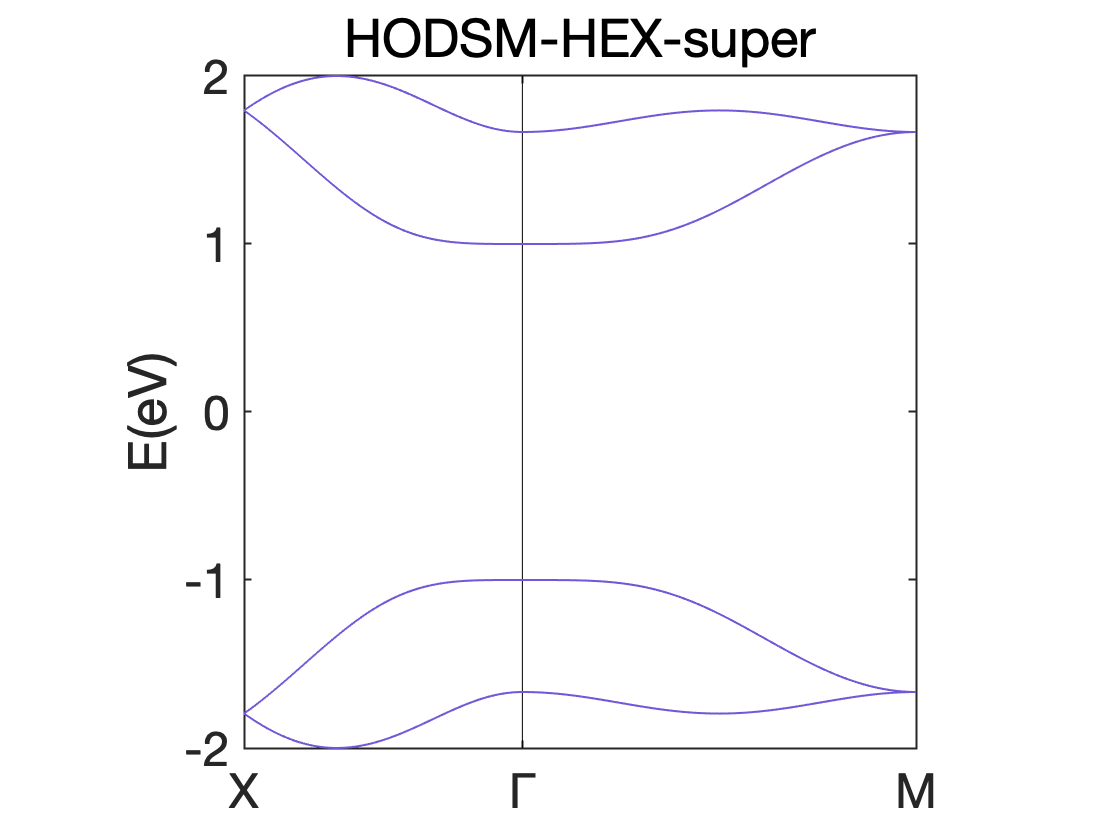

EIGENCAR = BHZ_TB_super_n.EIGENCAR_gen();
bandplot(EIGENCAR,[-2,2],'title',"HODSM-HEX-super",'KPOINTS','KPOINTS_4');

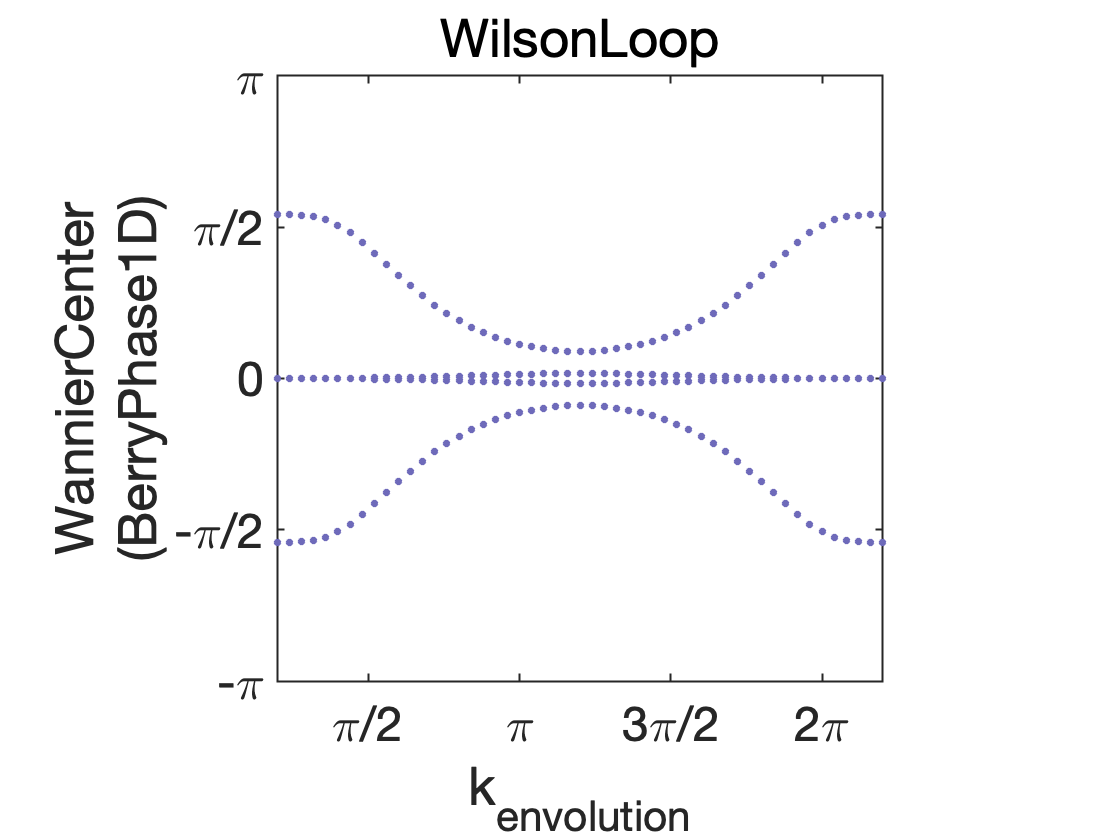

[BFCAR,~,klist_l] = BHZ_TB_super_n.WilsonLoop('knum_int',101,'kstart',[0,0,0.1],'kevolution',[1,0,0],'kintegral',[0,1,0],'cartesian',false);
[fig,ax] = vasplib.WilsonLoopPlot(BFCAR,klist_l);          

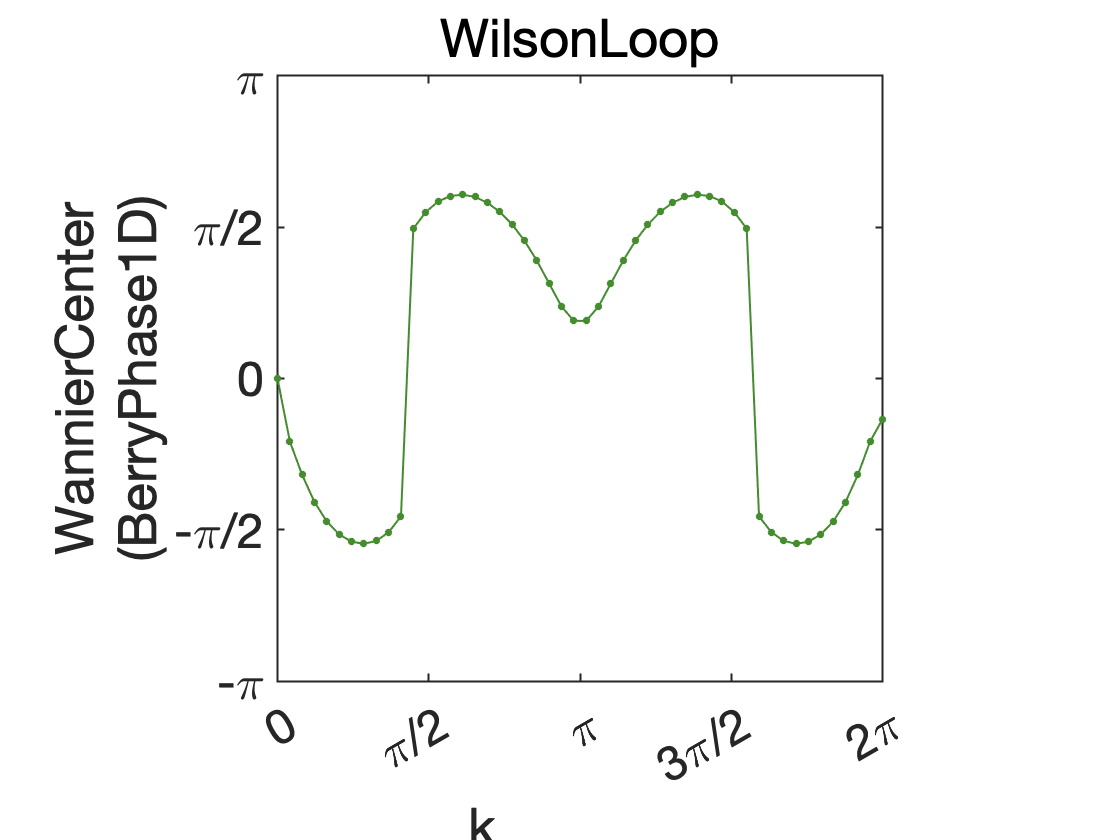

[nested_BFCAR,~,nested_klist_l] = BHZ_TB_n.nested_WilsonLoop('knum_int',31,'kevolution',[1,0,0],'kintegral',[-1,2,0]/2);
[fig2,ax2] = vasplib.WilsonLoopPlot((nested_BFCAR),nested_klist_l,'LineSpec','-o');

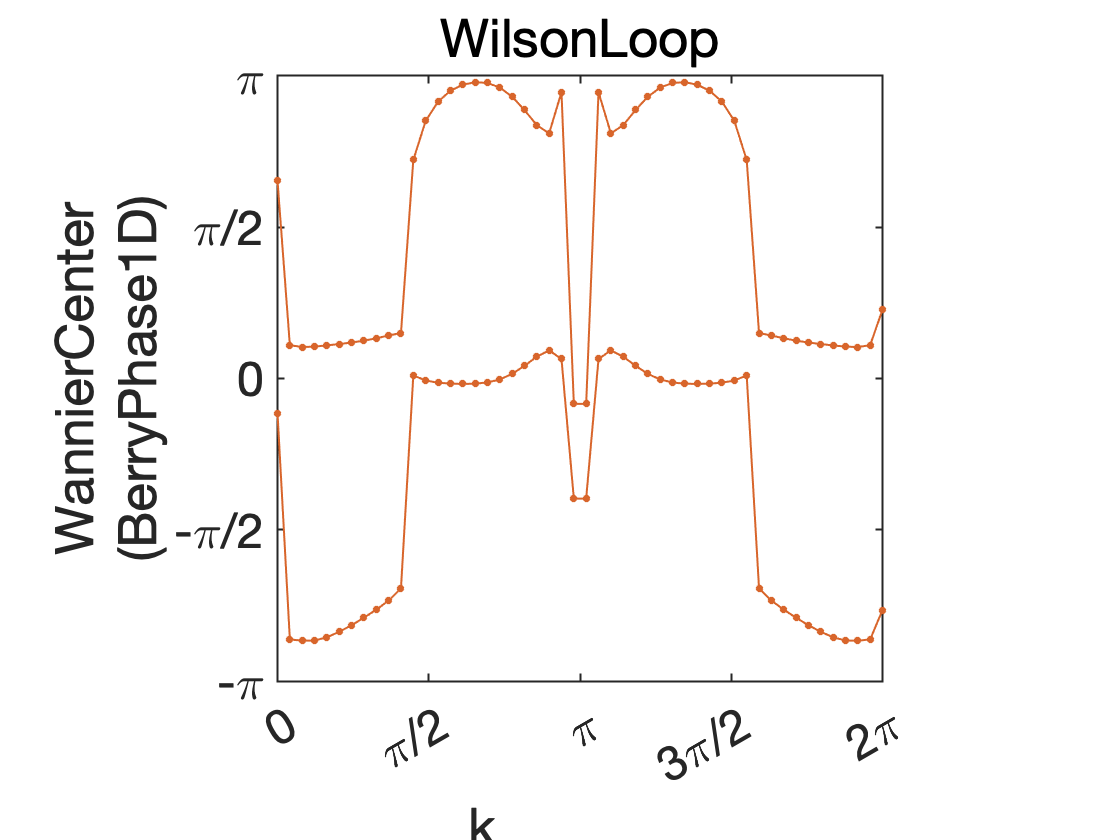

[nested_BFCAR,~,nested_klist_l] = BHZ_TB_super_n.nested_WilsonLoop('knum_int',31,'kevolution',[0,1,0],'kintegral',[1,0,0]);
[fig2,ax2] = vasplib.WilsonLoopPlot((nested_BFCAR),nested_klist_l,'LineSpec','-o');

test = 2
if test  == 1
    vacuum_mode = 1;
    kpoints = [0 0 1/6];
    Nslab = [20 20 1];
    np = 1;
    norb_enforce = -1;
    fermi = 0;
    KPOINTS_wire = 'KPOINTS_wire';
    cmap = turbo;
    fontname = 'Helvetica';
    [EIGENCAR_wire,orb_list,WEIGHTCAR,klist_l,kpoints_l,kpoints_name]  = BHZ_TB_n.EIGENCAR_gen_wire(Nslab,fermi,norb_enforce,KPOINTS_wire,vacuum_mode,np);
     pbandplot(WEIGHTCAR,EIGENCAR_wire,[-1,1],'Wire-BHZ-HODSM_hex-fat-hinge',cmap,klist_l,kpoints_l,kpoints_name);

end
